# Automatic Indentification of Glaucoma Using Deep Learning Methods

#### By Allan Cerentini

*Architecture****: *****Transfer Leanring **

                     **Pretrained GoogLeNet **

*Preprocessing****: *****Resize image to 224*224**

*DataSet**** : *****RIM-ONE V2**

                **Total Image Count: 455**

**                Normal Images: 255**

*Author:* **Gyanendar Manohar (R00207241)**

*Date:**** 27/02/2022***

***==========================================================================================***

### Set Random Seed

rng(50)

### Load Dataset


image_data_store = imageDatastore('C:\gyani\Projects_MS\code\dataset\RIMONE-db-r2','IncludeSubfolders',true,'LabelSource','foldernames');
[x_train_ds,x_test_ds] = splitEachLabel(image_data_store,0.9,'randomized');
numClasses = numel(categories(x_train_ds.Labels))

numClasses = 2

### GoogLeNet

googLe_net = googlenet;
input_size = googLe_net.Layers(1).InputSize

input_size =    224   224     3


### Augment Image

resized_train = augmentedImageDatastore(input_size(1:2),x_train_ds);
resized_test  = augmentedImageDatastore(input_size(1:2),x_test_ds);

# Transfer Larening

### Replace top layer


googLe_layer_graph = layerGraph(googLe_net); 

new_fully_connected_layers = fullyConnectedLayer(numClasses, 'Name','new_fc', ...
                            'WeightLearnRateFactor',0.1,'BiasLearnRateFactor',0.1);


replaced_layer_graph = replaceLayer(googLe_layer_graph,'loss3-classifier',new_fully_connected_layers);

### Make Final

newClassLayer = classificationLayer('Name','new_classoutput');
final_graph = replaceLayer(replaced_layer_graph,'output',newClassLayer);

### Freez Initial Weights

layers = final_graph.Layers;
connections = final_graph.Connections;
layers(1:10) = freezeWeights(layers(1:10));
final_graph = createLgraphUsingConnections(layers,connections);

### Train Network

### FineTuning

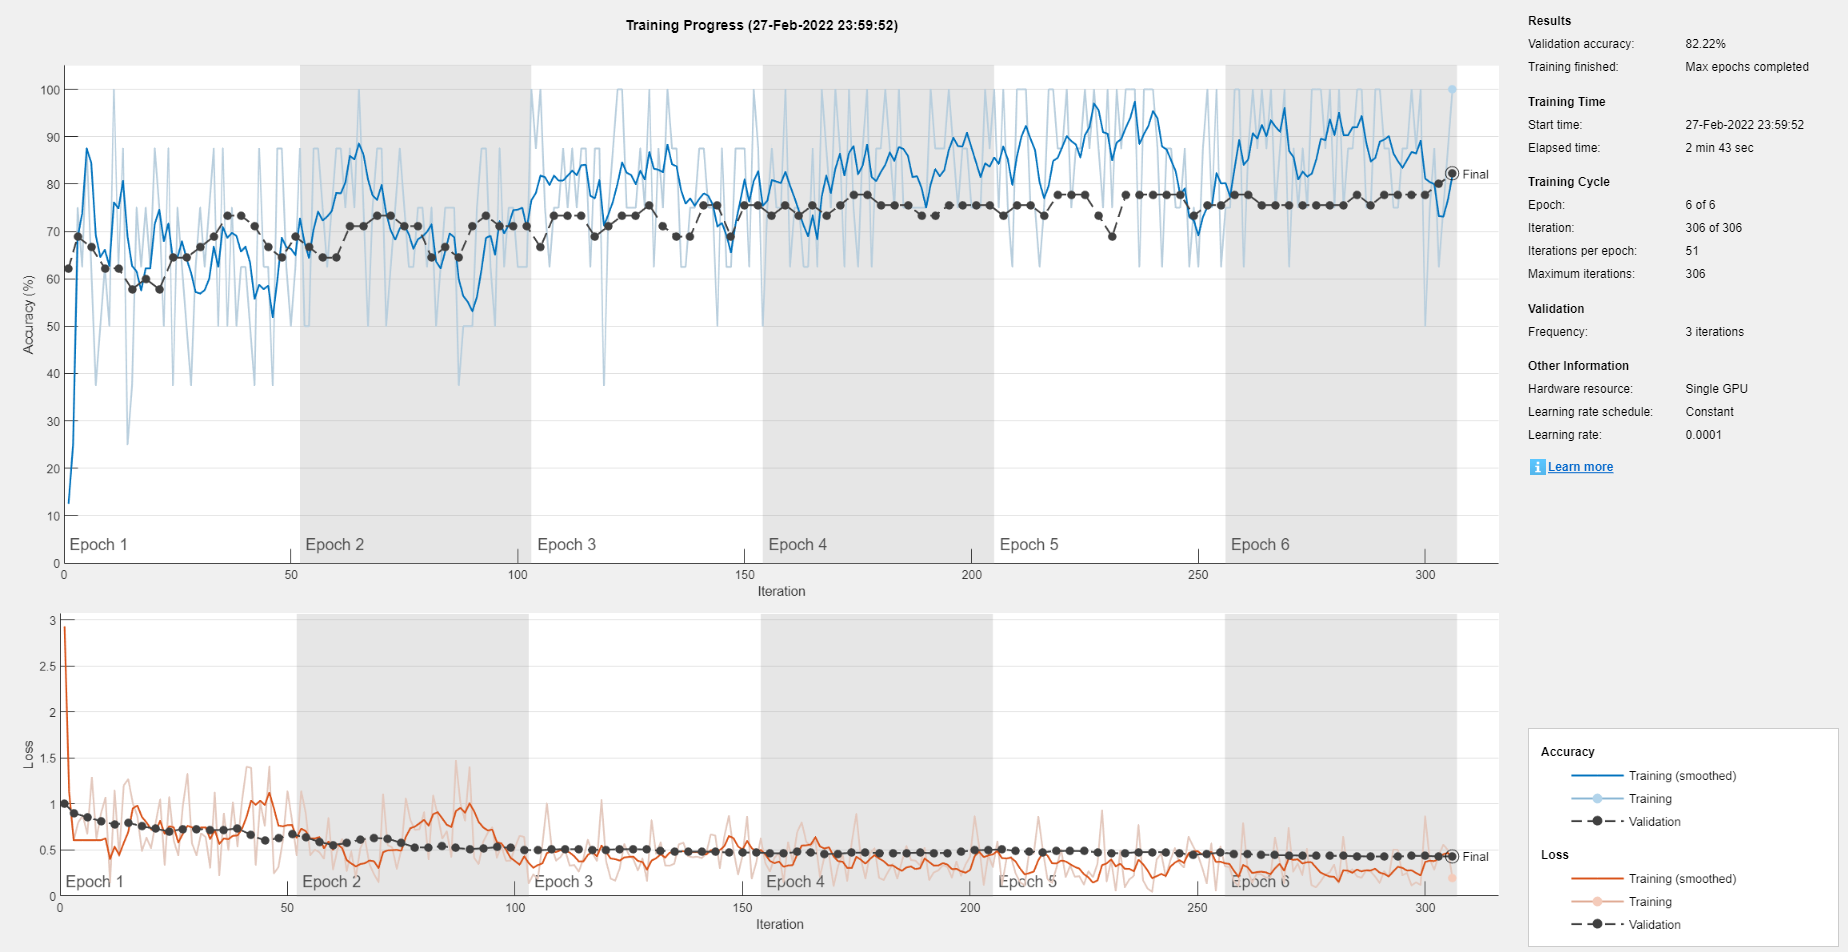

options = trainingOptions('sgdm', ...
    'MiniBatchSize',8, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',resized_test, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

trained_model = trainNetwork(resized_train,final_graph,options);

### Validation Accuracy

[y_predicted,probs] = classify(trained_model,resized_test);
accuracy = mean(y_predicted == x_test_ds.Labels)

accuracy = 0.8222